# `Project: Metabolic Exploration of Fibroblasts in Breast Cancer`

### `Objetive: `

`Explore metabolic behavior in breast cancer microenviroment fibroblast.`

### `Methodology description:    `

`In the present project, various genomic-scale models of fibroblasts with specific contexts are intended to be utilized. These models have been previously generated by integrating a generic model with omics information. The aim is to study the metabolism of these cells in fibroblast - tumor cells. The project encompasses 14 specific models from 7 patients, where each patient is represented by two models: a control model of normal fibroblasts (NF) and a cancer-associated fibroblast (CAF) model.`

`The CobraToolbox tools will be employed to simulate two ``in silico experiment`` aimed at identifying metabolic and genetic patterns in breast cancer-associated fibroblasts interaction. The experiment include:`

- `Metabolic flux comparison in CAFs and NFs models.`

#### `Authors: Rigoberto Rincón Ballesteros, Ramyet Sotelo Rodríguez, Bruno Salvador Santana Campos, Josué González Sandoval, Juan Carlos Kelly Naranjo.`

#### `Date: 11/31/2023`

#### `CobraToolbox`

`Initializing CobraToolbox is required before conducting our experiment in order to use the tools it provides. Additionally, we can define the optimizer of our choice; in this particular project, we use "mosek."`

initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2023
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.41.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Original LP has 1 row, 2 columns, 1 non-zero
Objective value = 0
OPTIMAL SOLUTION FOUND BY LP PRESOLVER

 > [glpk] Primal optimality condition in solveCobraLP satisfied.
 > [mosek] Primal optimality condition in solveCobraLP satisfied.
 > [mosek] Dual optimality condition in solveCobraLP satisfied.

 > [matlab] Primal optimality condition in solveCobraLP satisfied.
   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:    

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    0 	    0 	    0 	    0 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek        	active        	    1 	    - 	    1 	    - 	    - 	    1
	matlab       	active        	    1 	    - 	    - 	    - 	    

changeCobraSolver('mosek','all')


 > changeCobraSolver: MOSEK interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for LP problems has been set to mosek.

 > changeCobraSolver: MOSEK interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for QP problems has been set to mosek.

 > changeCobraSolver: MOSEK interface added to MATLAB path.
 > isCompatible: The compatibility can only be verified on Windows 7 and Windows 10.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2023a.
 > changeCobraSolver: Solver for EP problems has been set to mosek.
 > changeCobraSolver: Solver mosek not supported for problems of type MILP. Currently used: glpk 
 > changeCobraSol

ans = logical
   1


#### `Loading models`

`For the purposes of this project, it has been decided to store the information generated throughout the script in structured arrays, where we can create a field for each specific model. First, we define a structured array called "modelsNames" and load the models using the built-in MATLAB function "load( )".`

% cell array of models names
modelsNames = {'P1_CAFs_Xomics';'P1_NFs_Xomics';'P2_CAFs_Xomics';'P2_NFs_Xomics';'P3_CAFs_Xomics';'P3_NFs_Xomics';...
               'P4_CAFs_Xomics';'P4_NFs_Xomics';'P5_CAFs_Xomics';'P5_NFs_Xomics';'P6_CAFs_Xomics';'P6_NFs_Xomics';...
               'P7_CAFs_Xomics';'P7_NFs_Xomics'};

% define a struct array to load models and define the current path
models = struct;    
currentPath = pwd;

% load each specific model and save it in models array
for i=1:numel(modelsNames)
    % define a file name based on modelsNames array
    path = fullfile(currentPath, filesep, 'specific_Models',filesep, modelsNames{i}, filesep);
    fileName = [path,modelsNames{i},'_specificModel.mat'];
    
    % load the model
    model = load(fileName);

    % saving model
    models.(modelsNames{i}) = model.specificModel;  
end

`Experiment 1:`

`Metabolic Flux Comparison`

`For this experiment, we will determine the metabolic flux vector for each of your models through an optimization method. In this case, the intention is to use an objective function based on minimizing the product of the L2 norm and the weight vector derived from the gene expression data used to generate the specific models. We will employ a function from CobraToolbox called "modelMultipleObjectives" for this purpose.`

`The generated vectors will be stored in a structured array named "modelsVectors," containing a field for each model. Within each model, there will be two options: the original vector with the same name as the chosen objective function, and, on the other hand, the scaled vector by a factor of 10,000. This is for the purpose of facilitating visualization and subsequent result analysis.`

% struct array of flux vectors for each model
modelsVectors = struct; 

% defining the objective function to use
param.objectives = {'Weighted2normGE'}; 

% determine flux vectors and save them in modelsVectors array 
for i=1:numel(modelsNames)
    % selecting a model and apply function to determine metabolic flux vector
    model = models.(modelsNames{i});   
    solution = modelMultipleObjectives(model,param); 

    % save flux vector in modelsVectors array
    modelsVectors.(modelsNames{i}) = solution;
   
    % scale flux vector multiplying by a factor of 10,000 and saving it in other field 
    for j=1:numel(param.objectives)
        modelsVectors.(modelsNames{i}).([param.objectives{j},'_Scaled']) = solution.(param.objectives{j});  % scaling the metabolic flux vector
        scaledVector = (modelsVectors.(modelsNames{i}).([param.objectives{j},'_Scaled']).x);
        modelsVectors.(modelsNames{i}).([param.objectives{j},'_Scaled']).x = (scaledVector*10000);
    end
end

`Once the metabolic flux vectors have been obtained, we can define reactions of interest for our study. In this case, we have chosen to explore the metabolic flux behavior in seven specific reactions: glucose exchange, lactose exchange in its D and L forms, pyruvate exchange, L-alanine exchange, proline exchange, and ATP maintenance reaction. These reactions were selected based on the study by Kay, E., & Zanivan, S. (2021), where they describe some of the key metabolic reactions in the interactions between cancer-associated fibroblasts (CAFs) and tumor cells.`

% cell array of abbreviations for reactions of interest
rxnsOfInterest = {'EX_lac__L_e','EX_pyr_e','EX_ala__L_e','EX_pro__L_e','ATPS4mi'};

% struct array to saved rxns IDs in each model
rxnsOfInterestIDs = struct; 

% looking for rxns IDs in each model
for i=1:numel(modelsNames)
    for j=1:numel(rxnsOfInterest)
        % saving ID in rxnsOfInterestIDs array
        rxnsOfInterestIDs.(modelsNames{i}).(rxnsOfInterest{j}) = findRxnIDs(models.(modelsNames{i}),{rxnsOfInterest{j}});
    end
end

% cell array of names for reactions of interest
rxnsOfInterestNames = {'L Lactate Exchange','Pyruvate Exchange','L Alanine Exchange','L Proline Exchange','ATP Synthase '};

`Finally, we can compare the fluxes of the reactions of interest between the models. It has been decided that, due to the nature of the data, we will compare the flux of reactions between cancer-associated fibroblasts (CAF) and normal cells (NF) within each patient. This is because comparisons between patients could be somewhat misleading due to the high variability in clinical characteristics among them.`

`For this purpose, a function called "barPlotComparison" has been created. This function aims to take as arguments the structured arrays generated so far, as well as the reactions of interest, in order to generate a bar plot that helps visualize how the flux behaves between cancer-associated fibroblasts (CAFs) and normal cells (NF) for each patient.`

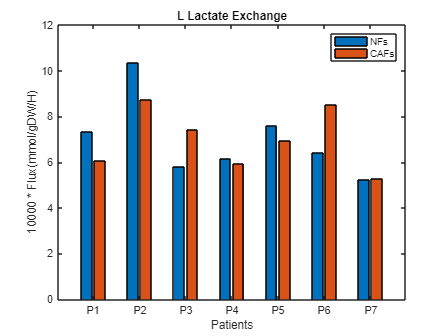

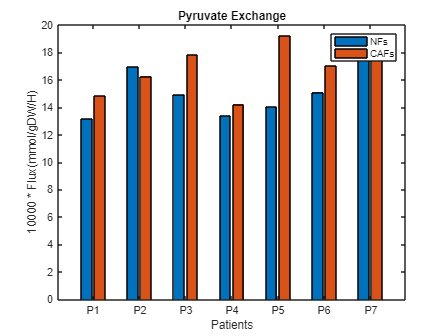

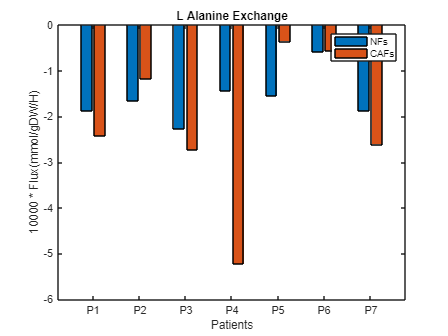

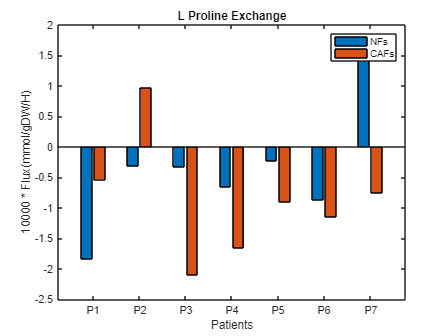

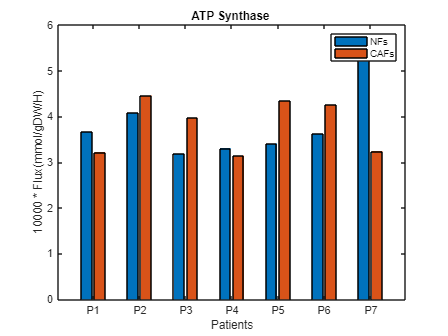

% create a figure to represent flux comparison for each rxn of interest
for i=1:numel(rxnsOfInterest)
    % selection of rxn of interest
    rxnOfInterest = rxnsOfInterest{i};

    % using function to compare fluxes and create a bar plot
    bar = barPlotComparison(modelsNames,modelsVectors,rxnsOfInterestIDs,rxnOfInterest,'Weighted2normGE'); % barplot creation with barPlotComparison function
    xlabel('Patients');
    ylabel('10000 * Flux(mmol/gDW/H)')
    legend('NFs','CAFs');
    title(rxnsOfInterestNames(i));  % name of rxn analyzed in each bar plot generated
end

`Results: As outcomes, we will generate a figure for each reaction of interest. These figures will illustrate the comparison between the fluxes in cancer-associated fibroblasts (CAF) and normal cells (NF) for each patient. Each figure is planned to be stored for subsequent presentation and result analysis.`